# ISB705: Advanced Systems Biology II

**Maria P10ires Pacheco, Tamara Bintener, and Thomas Sauter**

Hi! 

Welcome to the Practicals in Systems Biology. **Please read the text carefully. **

This is an interactive Matlab script you can work through at your own pace.

Make sure to run each section by pressing the "Run Section" in the toolbar (Live Editor) to answer the questions and see the output code. Alternatively, you can also use CRTL+ENTER. 

If you simply select and then run your code, you will not see the output inside of the live script but in the command window.

**Let us start by entering your name:**

simply click on the "*run section*" button. The inputs will be entered in the command window if no answer has been given previously.

clear all % this clears all your workspace variables. It helps you to have a fresh start in your script

delete clone*.log %delete some files generated by cplex

% feature astheightlimit 2000 %since a never version of matlab, this small code is needed for the model reconstruction

path = '\\atlas.uni.lux\fstc_sysbio\10- MISB_Teaching\ISB705_2023\For teachers\Day 3\Days 3 and 4'; % save working path

addpath(genpath(pwd)) %add the current folder and all subfolders to the Matlab path

cd(path)

prompt = ('Hi! What is your name?\n');

feature astheightlimit 2000

ans = 'feature astHeightLimit 2000'

this part is not mandatory to run, leave it commented

% addpath(genpath('C:\Program Files\IBM\ILOG\CPLEX_Studio128\cplex\Matlab')) % add cplex to the path
% addpath(genpath('C:\cobratoolbox-master')) % add the cobra toolbox
% rmpath(genpath('C:\cobratoolbox-master\src\dataIntegration\transcriptomics\FASTCORE')) %remove Cobra fastcore

# **Chapter 1: Getting to know genome-scale metabolic models**

Genome-scale metabolic reconstructions or models are a collection of currently known metabolic processes known to happen in a given cell at some time point. They contain information on the reactions, metabolites, and genes as well as their relation with each other. Because the models contain every known reaction that takes place in a cell, they do not represent a specific tissue or cell type. 

The first metabolic models were built manually with the help of sequencing data and data mining of biochemical databases and literature. This process can, to some extent, be automated but each model still needs to be refined.

Here is a basic 4-step workflow for a reconstruction:

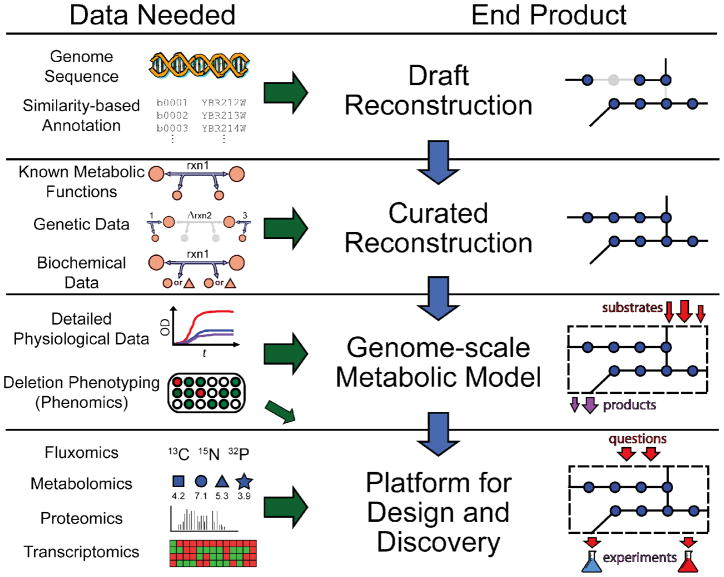

[https://www.ncbi.nlm.nih.gov/pmc/articles/pmid/19116616/](https://www.ncbi.nlm.nih.gov/pmc/articles/pmid/19116616/) for more information.

There also exists a more complex 96 step protocol: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3125167/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3125167/) 

There exist many different metabolic models for many different species. For humans, the Recon and HMR models are most widely used. Recently, a new model, Human 1, was released. With more available knowledge, these models are also updated and new versions are published. For this part of the course, **we will use Recon 3D**, a recently published metabolic model (Brunk et al., 2018). If you are curious about the model, feel free to read: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5840010/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC5840010/) 

In the last 2 days, you were working with smaller, more comprehensible models. Recon 3D has over 10'000 reactions and 5'000 metabolites. Every reaction and metabolite can be searched for in [https://www.vmh.life/](https://www.vmh.life/) . You also find a visualization of the metabolic network contained in the model:

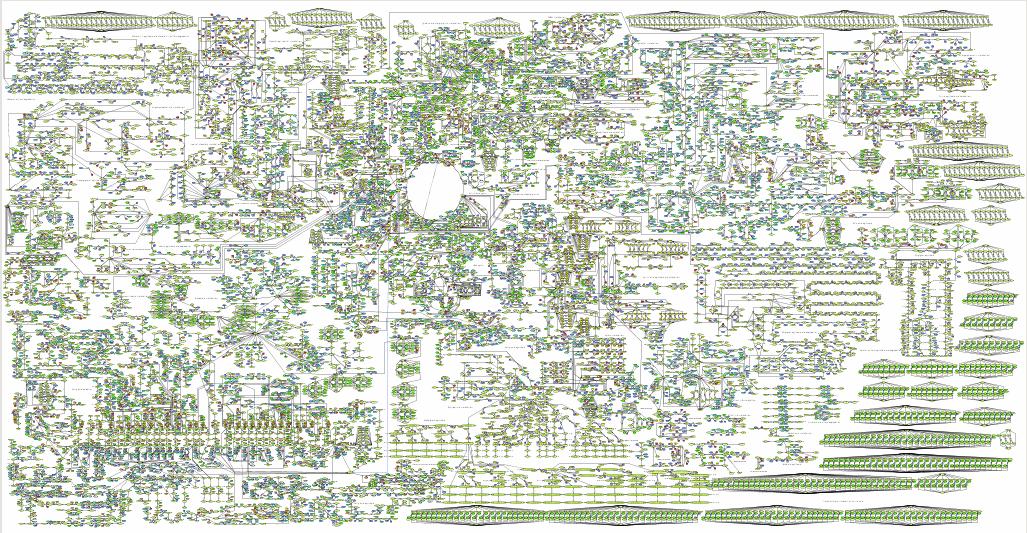

[https://www.vmh.life/#reconmap2](https://www.vmh.life/#reconmap2) in case you want to have a better look.

Load the provided model (called *"model_practicals.mat"*) and click on the "model" variable in the workspace on the right to inspect it. 

The model variable is a structure array and groups related data using data containers called *fields*:

- *S            *called S matrix, gives information about which metabolites takes place in which reaction with their stoichiometric information. Also called the stoichiometric matrix.

- *rxns*        a list of reactions contained in the model

- *mets*       a list of metabolites contained in the model

- *lb*            lower bounds of the reactions

- *ub*           upper bounds of the reactions 

- *genes*     a list of genes contained in the model 

- etc

We will learn more about these fields during this practical. 

load model_practicals.mat % load used to load previously saved .mat files
disp('Scroll down to see all the fields')

Scroll down to see all the fields


model % displays information about the model variable

model = struct with fields:
                      S: [5837×10601 double]
                   mets: {5837×1 cell}
                      b: [5837×1 double]
                 csense: [5837×1 char]
                   rxns: {10601×1 cell}
                     lb: [10601×1 double]
                     ub: [10601×1 double]
                      c: [10601×1 double]
                 osense: -1
                  genes: {2248×1 cell}
                  rules: {10601×1 cell}
             metCharges: [5837×1 int64]
            metFormulas: {5837×1 cell}
              metSmiles: {5837×1 cell}
               metNames: {5837×1 cell}
              metHMDBID: {5837×1 cell}
         metInChIString: {5837×1 cell}
              metKEGGID: {5837×1 cell}
           metPubChemID: {5837×1 cell}
            description: 'Recon3DModel.mat'
                grRules: {10601×1 cell}
             rxnGeneMat: [10601×2248 double]
    rxnConfidenceScores: [10601×1 double]
               rxnNames: {10601×1 cell}
           

**Notes on how to answer each question:**

For each question, when you run the **Answer section **via the run *section button*, you will be given 3 consecutive attempts to answer the question. (Do not worry you can answer a question as many times as you want, there are no penalties). During these 3 attempts, you will be unable to use the workspace or the command window until you either answer correctly or fail at answering 3 times. So please make sure that you do all the needed operations, checks, or calculations before running the **Answer section.** 

You can and should use the provided section to enter and run your code to find the answer to the question. Using the command line is fine but writing (and saving!) your code will make it easier for you if you ever come back to this script in the future. It also helps for debugging and create reproducible results. Feel free to use as much space for your code as you need.

There can be more ways to get to the correct answer.

**Help Function**

Make use of the *doc* and *help* functions in Matlab to understand what a function is doing.

**Hints**

If you are stuck on a question, you can use the provided *hint* function, by using *hint(1)*, to get a hint for the first question.

## **Question 1: **

How many fields are in the model variable? You can answer the question by running the Answer section. Hint: fieldnames.Use doc fieldnames to know more about the syntax.

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer**

Please type the number.

 Ques(1)

**Additional notes**

The *Value* column, next to the *Field* column in the model variable (both in your workspace and when you open the model structure) gives you information about the dimensions of a variable. You can access fields in a structure by using a dot: *structure****.****field1*.

For example, the dimensions of the S matrix are 5387 by 10601, meaning that the S matrix contains 5387 metabolites and 10601 reactions. 

You can also check its size by accessing the *S* field from the model structure: 

size(model.S)

The first number always gives you the 1st dimension (rows) of the matrix and the second one gives you the second dimension (columns) and so on.

## **Question 2:**

What is the number of genes in the model? 

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer**

Please type the number.

Ques(2)

## **Question 3**

Obviously, there is more than 1 reaction per pathway and, therefore, the pathways are repeated several times. 

How many unique pathways are in the model?

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer**

Ques(3)

**Pathways**

Now that we know how many unique pathways there are, you can also determine the number of reactions in each pathway by typing:

[pathway_count, pathway_names] = histcounts(categorical(model.subSystems)) %histcounts is a very useful function! Open its documentation to see more.
T = table(pathway_names', pathway_count')% scroll down to see the number of reactions every pathway, alternatively you can also open the T variable
T.Properties.VariableNames = {'pathway_names','pathway_count'} %this changes the names of the columns in a table.

We can also plot the number of reaction per pathway in a sorted barplot:

[~,I] = sort(T.pathway_count,'descend'); %sort by descreasing pathways counts
figure
bar(T.pathway_count(I))
xlim([1 numel(T.pathway_names)])
% xticklabels(T.pathway_names(I)) %enable this to see the names, the figure will be very small

pathway_count =           13           1          32          26          41          40          10         185          12          47           3           8         242          44          45          20           4          14          15           3          12         573          93        1787         961         239          59          23          14          16          16         165          47          42          71          14           4          19          27           2          14           5          65          76          22           8           3           9           1          31


pathway_names = 1×103 cell array
    {'Alanine and aspartate metabolism'}    {'Alkaloid synthesis'}    {'Aminosugar metabolism'}    {'Androgen and estrogen synthesis and metabolism'}    {'Arachidonic acid metabolism'}    {'Arginine and proline metabolism'}    {'Beta-Alanine metabolism'}    {'Bile acid synthesis'}    {'Biotin metabolism'}    {'Blood group synthesis'}    {'Butanoate metabolism'}    {'C5-branched dibasic acid metabolism'}    {'Cholesterol metabolism'}    {'Chondroitin sulfate degradation'}    {'Chondroitin synthesis'}    {'Citric acid cycle'}    {'CoA catabolism'}    {'CoA synthesis'}    {'Cytochrome metabolism'}    {'D-alanine metabolism'}    {'Dietary fiber binding'}    {'Drug metabolism'}    {'Eicosanoid metabolism'}    {'Exchange/demand reaction'}    {'Fatty acid oxidation'}    {'Fatty acid synthesis'}    {'Folate metabolism'}    {'Fructose and mannose metabolism'}    {'Galactose metabolism'}    {'Glutamate metabolism'}    {'Glutathione metabolism'}    {'Glycerophosph

xticks(1:numel(T.pathway_names))

T = 103×2 table
                           Var1                           Var2
    __________________________________________________    ____

    {'Alanine and aspartate metabolism'              }     13 
    {'Alkaloid synthesis'                            }      1 
    {'Aminosugar metabolism'                         }     32 
    {'Androgen and estrogen synthesis and metabolism'}     26 
    {'Arachidonic acid metabolism'                   }     41 
    {'Arginine and proline metabolism'               }     40 
    {'Beta-Alanine metabolism'                       }     10 
    {'Bile acid synthesis'                           }    185 
    {'Biotin metabolism'                             }     12 
    {'Blood group synthesis'                         }     47 
    {'Butanoate metabolism'                          }      3 
    {'C5-branched dibasic acid metabolism'           }      8 
    {'Cholesterol metabolism'    

xtickangle(60)

T = 103×2 table
                      pathway_names                       pathway_count
    __________________________________________________    _____________

    {'Alanine and aspartate metabolism'              }          13     
    {'Alkaloid synthesis'                            }           1     
    {'Aminosugar metabolism'                         }          32     
    {'Androgen and estrogen synthesis and metabolism'}          26     
    {'Arachidonic acid metabolism'                   }          41     
    {'Arginine and proline metabolism'               }          40     
    {'Beta-Alanine metabolism'                       }          10     
    {'Bile acid synthesis'                           }         185     
    {'Biotin metabolism'                             }          12     
    {'Blood group synthesis'                         }          47     
    {'Butanoate metabolism'                        

title('Number of reactions per pathway')

## **Question 4**

How many reactions belong to the  "Transport, extracellular" pathway?

% ---- enter your code here, then run the Answer section to enter the answer ---- 

**Answer**

Ques(4)

## Question 5

Find the names of the extracellular transporters.  Enter you code here.

% ---- enter your code here, then run the Answer section to enter the answer ---- 
%Trans_rxns=

**Answer**

Ques(5,Trans_rxns);

## Question 6

Let's have a look at the metabolites, what is the 59th metabolite called?

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer**

Please type the identifier name.

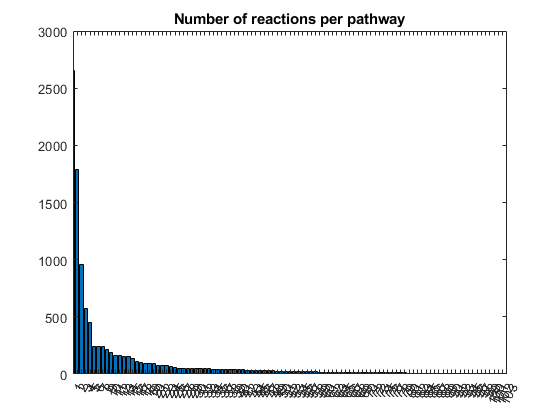

Ques(6)

**Additional notes**

As you can see, the metabolite is called XXX[c]. The letter you find in the brackets [] indicates in which compartment a metabolite is situated. In the provided model we have:

- [c] cytoplasm

- [e] extracellular

- [g] Golgi

- [l] lysosome

- [m] mitochondria

- [n] nucleus

- [r] reticulum

- [x] peroxisome

Let's create a new field in the model called metcomp. We first need to extract the compartments for each metabolite. Therefore, we are going to use regular expressions. Regular expression is very useful but somewhat difficult to apply without prior knowledge. If you want to have more information about it, feel free to check the Matlab documentation on regexp: 

% doc regexp

Because the regular expression functions are so diverse, there are several ways of accomplishing this, but for now, we will provide you with the code to extract the metabolites compartments. We will be removing the parts of the string you do not need:

model.metcomp = regexprep(model.mets, '(.*?)\[',''); % removes everything before the bracket, including the bracket
model.metcomp = regexprep(model.metcomp, ']',''); %remove the closing bracket

## **Question 7**

How many reactions take place in the cytoplasm?

% ---- enter your code here, then run the Answer section to enter the answer ----
[meta_count, meta_names] = histcounts(categorical(model.metcomp))
T = table(meta_names', meta_count')

**Answer**

Ques(7)

**Additional notes**

The reactions in the model are controlled by the expression of genes (or rather proteins and enzymes but in the model, they are referred to as genes). Several genes can be needed to activate a reaction, sometimes only one gene is needed. For diffusion reactions, no genes are needed to be present as these reactions take place regardless of gene activity.

The GPR (gene-protein-reaction) rules describe what genes are needed for a reaction to take place. If several genes are involved, Boolean OR or AND operators are used. The field is called *grRules* in the model.

Let's check out some reactions in the model.

model.grRules(1) % is not associated with any genes
model.grRules(96) %is associated with two genes using a Boolean OR
model.grRules(279) %is associated with two genes using a Boolean AND

## Question 8

In a GPR expression with a BOOLEAN OR, if one of the genes is active and the other is inactive, is the reaction active? (Yes/No)

**Answer**

answer with Yes or No. If you fail try to figure out why. 

Ques(8)

## Question 9

In a GPR expression with a BOOLEAN AND, if one of the genes is active and the other is inactive, is the reaction active? (Yes/No)

**Answer**

Ques(9)

## Question 10

What about this expression? If Gene 4 is expressed and the others are not, is the reaction active?

Gene 1 OR (Gene 2 AND Gene 3) OR Gene 4

**Answer**

Ques(10)

meta_count =            1           1        2125        1579         228           1         234         690          95         571         312


meta_names = 1×11 cell array
    {'A'}    {'B'}    {'c'}    {'e'}    {'g'}    {'i'}    {'l'}    {'m'}    {'n'}    {'r'}    {'x'}


# Chapter 2: Context-specific models

## 1) Consistent and m**edium constrained models**

In constraint-based modelling, for reactions to carry a flux (or be active), they have to be connected either directly or indirectly to the environment. This connection is made using exchange reactions that describe input and output reactions, also called uptake and secretion.

A gap or a dead end in the network will cause the associated reactions to be blocked i.e. unable to carry a flux.

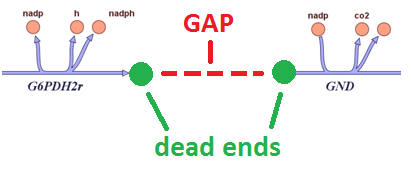

In order to perform any sensible analysis, any blocked reaction should be removed from the model to make it consistent. In a consistent model, every reaction is able to carry a non-zero flux. There exist several tools that check the consistency of a model and create a consistent model if this is not the case. 

For example, FASTCC (*Vlassis et al, 2014*) is widely used to quickly obtain a consistent model by checking if all the reactions in the model are interconnected. As seen in this example, metabolite C is a dead-end metabolite. By running FASTCC, the metabolite and the associated reaction can be removed from the output model.

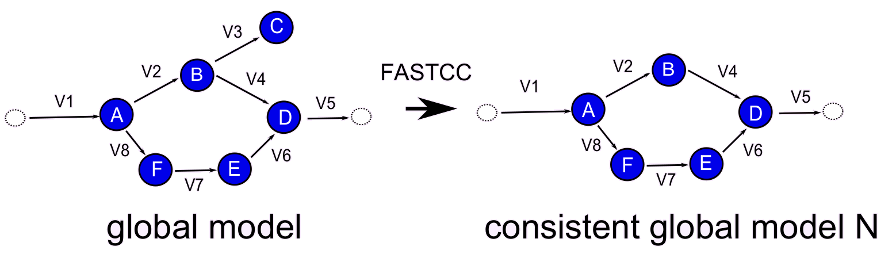

The output of Fastcc is a vector *A* that contains the indices of the reactions that can carry a flux i.e. are not blocked. In order to run FASTCC, we need to know if a reaction is reversible. Because this field does not exist in the mode, we need to create the field. We will assign to each reaction a 1 if the reaction is reversible and a 0 if it is not reversible (irreversible). A reaction is reversible if its lower bound is below 0 and it is irreversible if its lower bound is about or equal to 0. 

Our model has the lower bound *lb* field, so let us create the *rev* field for FASTCC:

 A = fastcc_4_rfastcormics(model, 1e-4, 0)

T = 11×2 table
    Var1     Var2
    _____    ____

    {'A'}       1
    {'B'}       1
    {'c'}    2125
    {'e'}    1579
    {'g'}     228
    {'i'}       1
    {'l'}     234
    {'m'}     690
    {'n'}      95
    {'r'}     571
    {'x'}     312


## Question 11

 A model in which all the reactions are connected directly or indirectly to the environment are called consistent. A reaction that can carry flux is called blocked. 

 Ques(11)

## Question 12

There is only one reaction in the model A. that is blocked. What is the name (model.rxns) of this reaction? Be careful with the spelling.

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer**

Ques(12)

ans = 1×1 cell array
    {0×0 char}


**Creation of a consistent model**

We have previously obtained the vector *A* containing the indices of the consistent reactions in the model. We will use this vector to build a model without any blocked reaction(s) called consistent_model. Therefore, we are going to remove these reactions using the *removeRxns* function from the model.

consistent_model = removeRxns(model, model.rxns(setdiff(1:numel(model.rxns),A))) % create a consistent model based on the vector A

ans = 1×1 cell array
    {'6822.1 or 6818.1'}


To check if the newly created model is consistent, we can run *fastcc* again, it will tell us that the input model is consistent:

fastcc_4_rfastcormics(consistent_model, 1e-4, 0);

ans = 1×1 cell array
    {'56301.1 and 6520.1'}


**Exchange reactions and medium constraints**

Exchange reactions are reactions that connect the system to the extracellular environment noted [e]. Not every exchange reaction can carry a flux in every condition. For example, if we take cells in a dish that are growing on a medium X, the cells are only able to import metabolites that are also found in the medium. To correctly model these cells, the model has to be constrained to only take up these available metabolites. 

The first step in constraining the model with the medium is to find its exchange reactions by using the function *findExcRxns*. Again, the output is a logical array that corresponds to 1 and 0 for each reaction in the model.

[EX] = findExcRxns(consistent_model)

## Question 13

How many exchange reactions are in the model?.

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer**

Ques(13)

If you want to know what metabolites are used in the exchange reactions you can print the equations of the reactions by using the *printRxnFormula *function:

printRxnFormula(consistent_model, consistent_model.rxns(find(EX))); % shows ALL exchange reactions

As you scroll through the equations, you see that there is only a metabolite on one side of the equation and nothing on the other. This means that the metabolite is secreted into the extracellular space (X -> ) or going out of the model. Other metabolites can either be secreted or taken up from the extracellular space (X <=> ).

Demand reactions are denoted by DM_ and sink reactions are denoted by sink_. These reactions allow for a limitless production or consumption of a metabolite.

## **Question 14**

To constrain a model, for every metabolite that is not present in the medium, the bounds of the exchange reactions that take up this metabolite has to be set to 0.

First, import the provided example medium with its composition:

load medium_example.mat

Elapsed time is 4.178535 seconds.


A =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


How many metabolites are present in the example medium?

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer **

Ques(14)

correct


ans = 'consistent'

## **Question 15**

Secondly, let us find the exchange reactions that are importing these metabolites from the cell into the model. These exchange reactions will be able to carry a flux. We can use the *findRxnsFromMets* function to find the reactions associated with a list of metabolites:

[Ex_open] = findRxnsFromMets(consistent_model, medium_example)

Find reactions that should be unable to carry a flux and save them in a variable called  "*Ex_to_close".*

% ---- enter your code here, then run the Answer section to enter the answer ----
%Ex_to_close = 

**Answer**

Ques(15, Ex_to_close);

consistent_model = struct with fields:
                      S: [5835×10600 double]
                   mets: {5835×1 cell}
                      b: [5835×1 double]
                 csense: [5835×1 char]
                   rxns: {10600×1 cell}
                     lb: [10600×1 double]
                     ub: [10600×1 double]
                      c: [10600×1 double]
                 osense: -1
                  genes: {2248×1 cell}
                  rules: {10600×1 cell}
             metCharges: [5835×1 int64]
            metFormulas: {5835×1 cell}
              metSmiles: {5835×1 cell}
               metNames: {5835×1 cell}
              metHMDBID: {5835×1 cell}
         metInChIString: {5835×1 cell}
              metKEGGID: {5835×1 cell}
           metPubChemID: {5835×1 cell}
            description: 'Recon3DModel.mat'
                grRules: {10600×1 cell}
             rxnGeneMat: [10600×2248 double]
    rxnConfidenceScores: [10600×1 double]
               rxnNames: {10600×1 cell}


## Question 16

Do you have to constrain the upper or the lower bounds in the model? Type *ub* for upper bounds and *lb* for lower bounds.

Ques(16)


The input model is consistent.
Elapsed time is 3.270108 seconds.


Now adjust the following code to change these bounds to zero. **Replace XX by either ub or lb**. This will change the bound to 0.

medium_constrained_model = consistent_model; %let us save the consistent model in case you make a mistake

EX = 10600×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


medium_constrained_model.XX(ismember(consistent_model.rxns,Ex_to_close)) = 0

After changing the bounds of these reactions, they will no longer be able to carry a flux and the model might become inconsistent again. We should run FASTCC again on the medium constrained model:

A = fastcc_4_rfastcormics(medium_constrained_model, 1e-4, 0); %takes approx. 15 minutes

## Question 17

After getting the indices of the consistent reactions from the medium constrained model, build the new consistent and medium constrained model by removing the inconsistent reactions from the medium constrained model. Name the model  medium_constrained_consistent_model

% ---- enter your code here, then run the Answer section to enter the answer ----
medium_constrained_consistent_model = removeRxns(medium_constrained_model, medium_constrained_model.rxns(setdiff(1:numel(medium_constrained_model.rxns),A)))

DM_13_cis_oretn_n_	13_cis_oretn[n] 	->	
DM_13_cis_retn_n_	13_cis_retn[n] 	->	
DM_Asn_X_Ser_Thr_ly_	Asn_X_Ser_Thr[l] 	->	
DM_avite2_c_	avite2[c] 	->	
DM_bvite_c_	bvite[c] 	->	
DM_core5_g_	core5[g] 	->	
DM_core7_g_	core7[g] 	->	
DM_core8_g_	core8[g] 	->	
DM_datp_m_	datp[m] 	->	
DM_datp_n_	datp[n] 	->	
DM_dctp_m_	dctp[m] 	->	
DM_dctp_n_	dctp[n] 	->	
DM_dem2emgacpail_prot_hs_r_	dem2emgacpail_prot_hs[r] 	->	
DM_dgpi_prot_hs_r_	dgpi_prot_hs[r] 	->	
DM_dgtp_m_	dgtp[m] 	->	
DM_dgtp_n_	dgtp[n] 	->	
DM_dsT_antigen_g_	dsT_antigen[g] 	->	
DM_dttp_m_	dttp[m] 	->	
DM_dttp_n_	dttp[n] 	->	
DM_ethamp_r_	ethamp[r] 	->	
DM_gncore2_g_	gncore2[g] 	->	
DM_gpi_sig_er_	gpi_sig[r] 	->	
DM_hretn_n_	hretn[n] 	->	
DM_kdn_c_	kdn[c] 	->	
DM_m_em_3gacpail_prot_hs_r_	m3gacpail_prot_hs[r] 	->	
DM_melanin_c_	melanin[c] 	->	
DM_mem2emgacpail_prot_hs_r_	mem2emgacpail_prot_hs[r] 	->	
DM_n5m2masn_g_	n5m2masn[g] 	->	
DM_oretn_n_	oretn[n] 	->	
DM_Ser_Thr_ly_	Ser_Thr[l] 	->	
DM_Ser_Gly_Ala_X_Gly_ly_	Ser_Gly_Ala_X_Gly[l] 	->	


**Answer **

Ques(17, A, medium_constrained_consistent_model);

## **2) Reconstruction of context-specific models using gene expression data**

Besides constraining a model with the medium composition, there are other ways of constraining a model. As stated in the beginning, a genome-scale metabolic reconstruction is not cell-type nor tissue-specific. In order to create a specific model, also called a context-specific model, we can use expression data to further constrain the reactions in the model because the reactions are linked to the genes via the GPR rules. The gene expression data allows us to determine which reactions in the model are more likely to be expressed or not in a specific context such as a disease.

The possibility to easily and quickly integrate gene expression data such as microarray or RNA-seq data, lead to the reconstruction of many published context-specific models, that can be tissue-specific, cell-specific, or condition-specific. Context-specific model building algorithms such as FASTCORE (Vlassis et al., 2014) and FASTCORMICS (Pacheco et al., 2015) or rFASTCORMICS (Pacheco et al., 2019) have specifically been developed for this task. They extract a consistent and context-specific model from a genome-scale metabolic reconstruction by keeping the reactions that are supported by the experimental data and most likely to be expressed in the context. 

In the following image, reactions v4 and v1 are highly supported by the data and the alternative pathway (v6, v7, v8) is removed in the final reconstruction.

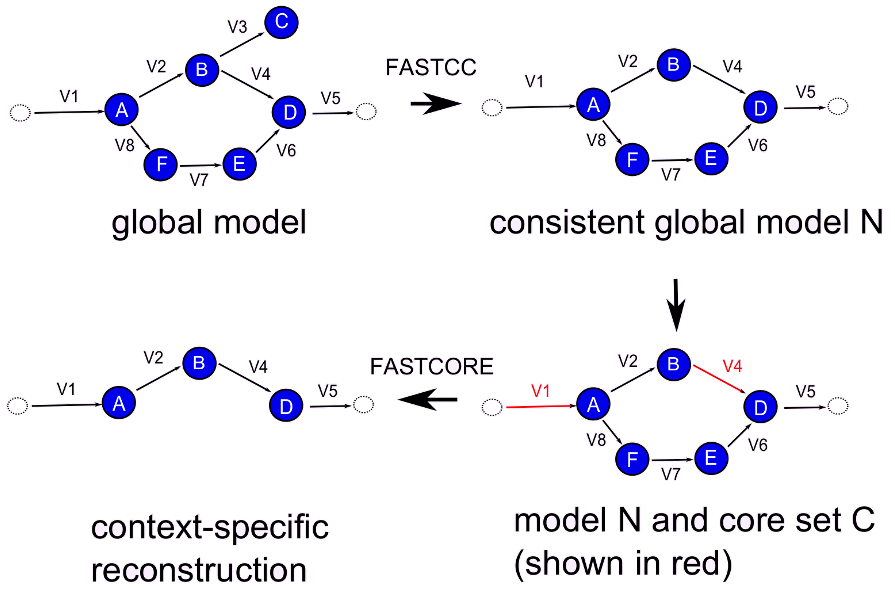

More information on these algorithms can be found here:

- FASTCORE:            [https://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1003424](https://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1003424)

- FASTCORMICS:     [https://bmcgenomics.biomedcentral.com/articles/10.1186/s12864-015-1984-4](https://bmcgenomics.biomedcentral.com/articles/10.1186/s12864-015-1984-4)

- rFASTCORMICS:    [https://www.sciencedirect.com/science/article/pii/S2352396419302853](https://www.sciencedirect.com/science/article/pii/S2352396419302853)

**Example**

In the following section, we will get some hands-on on how these algorithms work. Therefore, we are going to use the provided *data.mat* that contains RNA-seq data from 25 different breast cancer samples from the TCGA dataset. The data.mat file contains the variables *fpkm*, *colnames*, and *rownames*. Have a look at each variable to know what it contains.

In the first step, we will load and visualize the fpkm data. 

load data.mat % contains fpkm, colnames, and rownames
fpkm = table2array(fpkm); % transform table to array

Transforming the gene expression values into FPKM values is one way on how to process raw RNA-seq data. FPKM stands for Fragments Per Kilobase of transcript per Million mapped reads. In lay terms, one can say that it measures the activity of a gene. The higher the values, the more likely it is that the given gene is expressed in the sample. You can find more information on RNA-seq data here: [https://www.rna-seqblog.com/rpkm-fpkm-and-tpm-clearly-explained/](https://www.rna-seqblog.com/rpkm-fpkm-and-tpm-clearly-explained/) 

If we have look at the data distribution, we can see that the data is highly skewed to the left due to many lowly expressed genes and noise.

figure
hist((fpkm(:,1)),100);
ylabel('intensity'); xlabel('FPKM')

Because the distribution of the data is highly skewed, we will first log transform the data and then remove all the -Inf values.

signal = log2(fpkm(:,1)); % log2-transform the first sample of the fpkm data
signal(isinf(signal)) = -100000; %find the -Inf values and change them to -100000
signal = signal(signal>-10000); % remove samples with low expression

Let us plot the distribution of the first sample

figure
hist((signal),100);
ylabel('signal'); xlabel('log2(FPKM)')

Now that we have the distribution of the log-transformed fpkm data, we need to determine which genes are expressed and which genes are not expressed. We are therefore going to use the proposed method from rFASTCORMICS that will be called by using the *discretize_FPKM* function.

**Data discretization**

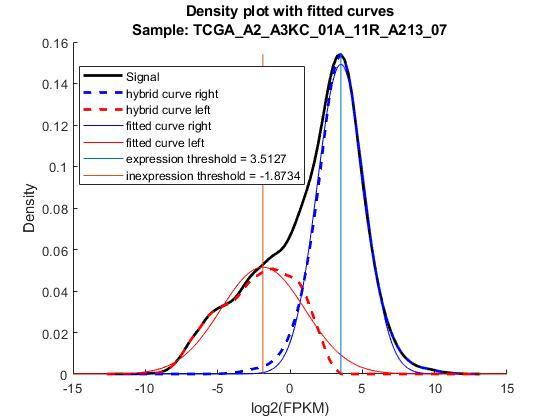

In blue and red are depicted two Gaussian curves that, according to Hart et al. and Pires Pacheco et al. correspond to the expressed genes and the noise, respectively. The signal curve is the sum of these partially overlapping curves. To obtain a context-specific model of quality, the number of reactions that are associated with genes in the blue curve should be maximized and the reactions associated with genes in the red curve should be minimized. 

Different tools have different approaches to integrate the problem of defining expressed an unexpressed genes, some approaches integrate continuous data while others prefer to binarize the data into 1 (expressed) and 0 (unexpressed).

We will use a discretization method, that will discretize the data with the help of several thresholds to determine sets of expressed (1), unexpressed (-1) and optionally unknown (0) genes. The approach of discretization was shown to be the most correct. 

% discretized = discretize_FPKM(fpkm, colnames,1); %with figures, will save figures in Figures folder
discretized = discretize_FPKM(fpkm, colnames);

Unrecognized function or variable 'Ex_to_close'.

**Mapping the gene expression data to reactions**

For this tutorial, we will use rFASTCORMICS, a member of the FASTCORE family specifically designed to integrate RNAseq data into genome-scale metabolic reconstructions. But before using rFASTCORMICS we need to understand a key aspect of context-specific model building: the mapping of the expression to the model reactions.

As we have seen before, the reactions of a model can be under the control of one or several genes, using the GPR rules in the *model.grRules* field we are able to map the gene expression to the *model.rxns* field. The field contains information on which genes control a reaction and what combination of gene(s) is necessary for the reaction to take place (Boolean AND and OR). 

## Question 18

Let's say a reaction is under the control of 4 genes:

- gene 1 has an expression of 100 fpkm

- gene 2 has an expression of 0.5 fpkm

- gene 3 has an expression of 200 fpkm

- gene 4 has an expression of 0.1 fpkm

What will be the expression associated with the reaction

`    (Gene 1 OR Gene 2) AND (Gene 3 OR Gene 4)`

`please indicate the value without the fpkm`

Ques(18)

## Question 19

The same can be done with discretized data: 

- gene 1 has a score of 1 (expressed)

- gene 2 has a score of 0 (unknown expression)

- gene 3 has a score of 1 (expressed)

- gene 4 has a score of -1 (not expressed)

`    (Gene 1 and  Gene 2 and Gene 3) or Gene 4 `

What will be the score associated with the reaction?

Ques(19)

## 3) Model reconstruction using rFASTCORMICS

Besides gene expression data, rFASTCORMICS needs other inputs. Below is the function:

`[model, A_final] = fastcormics_RNAseq(model, data, rownames, dico, already_mapped_tag, consensus_proportion, epsilon, optional_settings)`

`Inputs`

- **model **this model will be used to extract the context-specific model from

- **data **the discretized data with 1 for expressed genes, 0 for unknown expression and -1 for unexpressed genes

- **rownames** of the data corresponding to the gene names for each row in the data

- **dico **a dictionary to map the gene names to the gene names in the model (provided)

- **already_mapped_tag **should be 0 because the data has not been mapped to the GPR rules of the model

- **consensus_proportion **in case several samples are used to reconstruct a model, generally 0.9

- **epsilon **the flux threshold value, generally 1e-4

- **optional_settings **a struct with several subfields such as reactions that have to be included in the model and the medium composition 

Outputs

- **model** context-specific model based on the input data

- **A_final** a vector containing the indices of the reactions to be included in the output model

You can build two types of models with FASTCORMICS: either you create one model per discretized sample or you create one generic model from a set of samples. 

**In this tutorial, we will only be building one generic breast cancer model based on the 25 provided samples.**

Create your breast cancer model based on the first column of the data and the consistent model using rFASTCORMICS. We have provided the dico and some of the optional settings for you. 

load optional_settings
load dico

already_mapped_tag = 0;
consensus_proportion = 0.9;
epsilon = 1e-4;
biomass_rxn ='biomass_reaction'

## Question 20

Use the *fastcormics_RNAseq* function to create a generic context-specific model for breast cancer using all the discretized samples and the consistent model (not medium constrained).

Note that the context-specific model building process takes around 8 minutes.

What is the size of the context-specific model (number of reactions)?

Replace INPUT1, INPUT2

% ---- enter your code here, then run the Answer section to enter the answer ----
%INPUT1 =
%INPUT2 =
[consistent_model, ~] = fastcormics_RNAseq(INPUT1, INPUT2, rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings)

**Answer**

**What is the 1 st input and the 2nd input? **

Ques(20,INPUT1, INPUT2 );

Note: the model is also a direct output from FASTCORMICS, however, if you create many models it is better to suppress this output as it will only take up memory and slow down your computer. Saving the model reaction in a matrix is sufficient.

## Model optimization

## Question 21

Often, an objective function is already set in the model. By default, it is the biomass production, however, it is always good to confirm that you are using the correct objective function. You can either find it  by having a look the model.c field where 1 marks the objective function reactions or by using the *checkObjective* function:

checkObjective(consistent_model)
find(consistent_model.c) % index of the objective function

In this case, the objective of the model is the biomass maintenance reaction with the index 5626 (Biomass maintenance reaction without replication precursors) but we would like to change it to the complete biomass reaction. 

Find the index of the biomass reaction called "biomass_reaction"

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer**

type the index of the biomass reaction

Ques(21)

To change the objective function in the model you can either change the model.c field or use the changeObjective function. The output will be a struct/a new model, so no not forget to save it.

% idx = 
consistent_model = changeObjective(consistent_model,consistent_model.rxns(idx)); % you need to assign a new variable to save the new model, or overwrite the existing one

Now check if the objective function was changed successfully:

printObjective(consistent_model)

## Question 22

In this example, we will use the biomass production as the objective function. While optimizing for the biomass, we assume that the whole metabolism of a cell is designed to produce biomass to enable fast proliferation.

For which of the following examples is this assumption reasonable:

- a) neuron

- b) cancer cell

- c) E. coli 

- d) none of the above 

- e) all the above 

- f ) a and b

- g) b and c

- h) a and c

For which cells is the optimization of the biomass production reasonable? (a, b, c, d, e, f, g,h)

**Answer**

Ques(22)

**Optimization**

We can now optimize the model for its biomass production to get the maximal value through the biomass reaction. Note that we use the option 'max', because the want to obtain the flux distribution that allows the highest production of biomass. For other optimizations, minimization might be a better option.

changeCobraSolver('ibm_cplex');
solution = optimizeCbModel(consistent_model,'max')

The solution variable is again a structure with different fields. The field we are interested in is the* solution.f *field, it gives you the maximal value of the flux through the objective function. This value will be used in the single gen deletion for the wild type.

## Question 23

What is this maximal growth value for the consistent model?

Ques(23)

## In *silico* gene deletions

Computational models can be used to predict the effect of a gene deletion. Such an approach is called "**in silico gene deletion**" or "in silico knockouts". In order to perform the in silico deletion, we need to set an aim for the model, a function that we would like to optimize for or maximise the output called **objective function**. 

For example, we can define the objective function of the model to be the biomass production, which indicates the metabolic demands for the models as it contains the production of every known precursor for cell proliferation. Before the in silico gene deletion, the maximal/optimal flux through the biomass reaction is calculated. This value is usually called the growth rate or the wild type (WT).

During the in silico gene deletion, each gene is deleted one by one and every time the maximal/optimal flux through the biomass reactions is calculated. The output will be a vector of fluxes for each deleted gene  These values are usually called the growth rate of the knockout (KO). 

The *singeGeneDeletion* function from the COBRA Toolbox, as several inputs and outputs:

Inputs

- **model**: the model you want to perform the gene deletion on

- **method**: several methods exist on how to perform the gene deletion, we will use the default "FBA" or flux balance analysis method

- **geneList**: a list of genes you want to delete in case you do not want to delete all of the genes in the model.

- **verbFlag**: you can force the function to output some text

- **uniqueGene**: often in the models you have gene transcripts depicted by XXX.1 and XXX.2. By setting the uniqueGene input to 1, both genes will be deleted at the same time

Outputs:

- **grRatio**: an array the same size as the deleted genes, it is the growth ratio bnetween the KO and WT

- **grRateKO**: similar to the growth ratios but with full numbers

- **grRateWT**: a single number for the WT

- **hasEffect**: logical array if a gene deletion affects any reaction even if the effect is minimal, not used '~'

- **delRxns**: which reactions are affected by the gene deletion even if the effect is minimal, not used '~'

- **fluxSolution**: fluxes for each reaction and gene deletion, not used '~'

Let us perform singeGeneDeletion on the consistent model while optimizing for the biomass reaction to see what gene deletions affect the biomass.

[grRatio_consistent, grRateKO_consistent, grRateWT_consistent, ~, ~, ~, geneList_consistent] = singleGeneDeletion_MISB(consistent_model, 'FBA', [], 0, 1);

Now we will perform the single gene deletion on the generic breast cancer model. Do not forget to check for the objective function and change accordingly.

## Question 24

For the context-specific model:

BRCA_generic_model = changeObjective(BRCA_generic_model,'biomass_reaction');
printObjective(BRCA_generic_model)
[grRatio_BRCA, grRateKO_BRCA, grRateWT_BRCA, ~, ~, ~, geneList_BRCA] = singleGeneDeletion_MISB(BRCA_generic_model, 'FBA', [], 0, 1);
Results.grRatio_BRCA=grRatio_BRCA
Results.grRateKO_BRCA=grRateKO_BRCA
Results.geneList_BRCA=geneList_BRCA

The gene deletions of which reduce the biomass in the breast cancer model below 0.9.

% ---- enter your code here, then run the Answer section to enter the answer ----
% essential = 

What are the essential genes?

Ques(24, Results, essential)

## Question 25

Which genes completely reduce the flux through the biomass reaction to 0 in the breast cancer model?

% ---- enter your code here, then run the Answer section to enter the answer ----
%lethal=  

**Answer**

**enter the code **

Ques(25, Results, lethal)

**Visualization of the gene deletion results**

The growth ratios can easily be plotted to visualize how many genes affect the objective function. You will have to sort the growth ratios before plotting them.

Try to recreate the following figure:

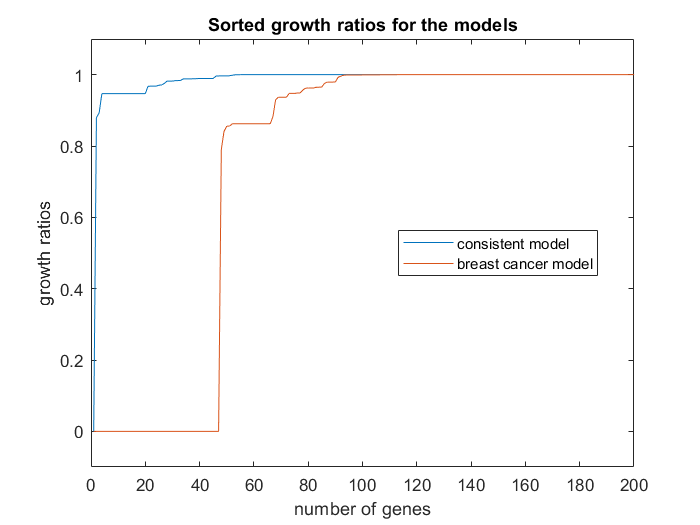

figure
hold on
% use the plot function to plot the growth ratios in ascending order

biomass_rxn = 'biomass_reaction'

g=sort(grRatio_BRCA,'ascend')

title('Sorted growth ratios for the models')
xlabel('number of genes')
ylabel('growth ratios')
xlim([0 150])
ylim([-0.1 1.1])
legend({'consistent model','breast cancer model'},'Location','best')

# Essential genes

Before we continue, we need to define an essential gene. In general, a gene is thought to be essential if its expression is needed for survival. For example, genes coding for enzymes that are needed in the central metabolism and energy supply as well as genes needed for the maintenance and translation of proteins are essential for all organisms.

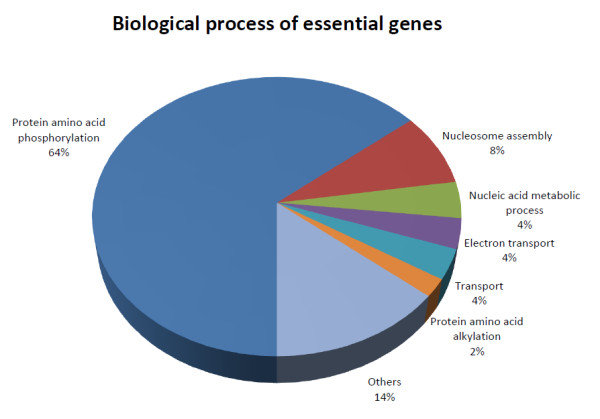

image from [https://bmcbioinformatics.biomedcentral.com/articles/10.1186/1471-2105-11-484](https://bmcbioinformatics.biomedcentral.com/articles/10.1186/1471-2105-11-484) 

There have been numerous attempts to experimentally find and validate the many genes that we can find in bacteria, viruses, and humans. Depending on your cell of interest, there are different methods available, each with their advantages and disadvantages. We will not go into detail about these methods but you can read the following review: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4441801/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4441801/) 

In these practicals, we will use the essential gene deletion data using CRISPR Cas9 from 

- Hart et al., 2015 [https://www.cell.com/cell/fulltext/S0092-8674(15)01495-6](https://www.cell.com/cell/fulltext/S0092-8674(15)01495-6) 

For the in silico gene deletion, we can say that a gene is essential if its deletion brings the growth ratio between the KO and WT to 0.5 or a reduction of 50% of the biomass. However, other thresholds can also be used depending on your goals and objective function.

We can easily transform our grRatio matrix into an essential gene matrix:

threshold = 0.5

Unrecognized function or variable 'INPUT1'.

essential_genes_BRCA = grRatio_BRCA <= threshold;

## Question 26

For a threshold of 0.5, how many genes are essential in the consistent model?

% ---- enter your code here, then run the Answer section to enter the answer ----

**Answer**

Ques(26)

## Question 27

For a threshold of 0.5, which genes are essential in the breast cancer model?

% ---- enter your code here, then run the Answer section to enter the answer ----
%geneList=

**Answer**

Ques(27,Results,geneList)

## Essential gene enrichment

Even though we performed *in silico* gene deletions in our models and defined the essential genes, we would like to assess how good our predictions are. In order to do so, we can compare the genes that we found to be essential, to lists of already validated essential genes. For example, we can use CRISPR-Cas9 gene screenings to compare our genes to the experimentally validated genes using a hypergeometric test. This test is used to assess if our findings were purely based on luck or if the findings are statistically significant. 

In this example, we use a large collection of CRISPR-Cas9 experimental data from:

- the SCORE database ([https://score.depmap.sanger.ac.uk/](https://score.depmap.sanger.ac.uk/)). More than 323 cell lines have been tested for gene essentiality

- Wang et al., 2015 "Identification and characterization of essential genes in the human genome". CRISPR-Cas9 on 4 human cell lines: KBM7, K562, Raji, and Jiyoye

- Hart et al., 2015 "High-resolution CRISPR screens reveal fitness genes and genotype-specific cancer liabilities". CRISPR-Cas9 on 5 cell lines.

- Blomen et al., 2015 "Gene essentiality and synthetic lethality in haploid human cells". CRISPR-Cas9 on KBM7 and HP1 cells.

Because the GeneEnrichment function takes as input only gene symbols, we have to transform the Entrez IDs to Symbols using the dico. We will use the saved GeneList for BRCA and extract the essential genes.

essential_genes_BRCA_Symbols = geneList_BRCA(essential_genes_BRCA); %get the identifiers for the essential genes
[~,ia,ib] = intersect(essential_genes_BRCA_Symbols, dico.ENTREZ); 
essential_genes_BRCA_Symbols(ia) = dico.SYMBOL(ib); %extract the symbols

[enrichment_BRCA] = GeneEnrichments(essential_genes_BRCA_Symbols)

- The 1st column indicates which dataset we are looking at. 

- The 2nd column gives the p-value for the enrichment

- The 3rd column gives how many genes there are in Recon3D with gene symbols

- The 4th column tells how many of the Recon3D genes are essential in the given database

- The 5th column gives how many genes we predicted to be essential in breast cancer

- The 6th column tells us how many of the predicted genes have already been validated experimentally.

We can export this table to Excel

writetable(enrichment_BRCA,'Enrichment_BRCA.xlsx')

We can sort the table by its enrichment score

[~,I] = sort(cell2mat(enrichment_BRCA.enrichment))
enrichment_BRCA(I,:)

**Underlying principle:**

The function that is used in the *GeneEnrichments* function is the ***hygecdf*** function in Matlab. The function takes 4 inputs: `hygecdf(x,M,K,N)`

- `x: number of correctly predicted essential genes in the context-specific model`

- `M: number of genes in the consistent model (metabolic genes)`

- `K: number of experimentally validated essential genes in the consistent model`

- `N: number of predcited essential genes in the context-specific model (essential context-specific metabolic genes)`

Here is an example:

- 1878 genes in Recon 3D, M =1878

- 170 validated genes in Recon3D, K = 170

- 47 predicted essential genes, N = 46

- 20 validated genes of the predicted genes, x = 20

M   = 1878;
K   = 170;
N   = 47;
x   = 20;

1-hygecdf(x-1, M, K, N)

The hypergeometric test returns a value below 0.05, meaning that our findings are significant and that the essential genes we predicted are not purely based on luck.

# Open questions for your report

- Why is the discretization of the fpkm values an important step for the model building process?

- Are there any other objective functions that you can optimize for? What other reactions are important for a cell to survive?

- Why is the optimization for the biomass reaction not always the best option?

- Which objective function(s) would you take for neurons for example? Why?

- Why are some gene deletions essentials while others are not?

- How does the number of essential genes change in function of the model size (number of reactions)? What is a possible explanation for this behaviour?

- What could be a benefit of performing double gene deletion for cancer models?

- Why don't we find the well known BRCA1 gene in the breast cancer model?

- What are the benefits of performing *in silico* experiments before *in vitro* experiments?

# Submission guidelines for day 3 and day 4

Besides answering these questions (you can either write it here or in a seperate .pdf file), please also send us back this script inlcuding the code you wrote with the saved answers (zipped).

**Please do not simply copy from your neighbor, solving and understanding the questions on your own will greatly help you in the second week!**